# Statistical Analysis of Mortality in Switzerland from 1960 to 2019

opts = spreadsheetImportOptions("NumVariables", 14);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A3:N62";
% Specify column names and types
opts.VariableNames = ["Year", "Total", "January", "February", "March", "April", "May", "June", "July", "August", "September", "October", "November", "December"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Import the data
myDeath = readtable("SwissMortality.xlsx", opts, "UseExcel", false)

myDeath = 60×14 table
    Year    Total    January    February    March    April    May     June    July    August    September    October    November    December
    ____    _____    _______    ________    _____    _____    ____    ____    ____    ______    _________    _______    ________    ________

    1960    52094     5291        5874      4437     4102     4154    3683    3792     3780       3819        4294        4167        4701  
    1961    51004     4751        4252      4431     4094     4211    4082    

clear opts

## Import population size and life expectancy data from spreadsheet

opts = spreadsheetImportOptions("NumVariables", 3);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A3:C62";

% Specify column names and types
opts.VariableNames = ["Year", "Population", "Life Expectancy"];
opts.VariableTypes = ["double", "double", "double"];

% Import the data
myPop = readtable("SwissPopdata.xlsx", opts, "UseExcel", false)

myPop = 60×3 table
    Year    Population    LifeExpectancy
    ____    __________    ______________

    1960    5.3602e+06        71.06     
    1961    5.5084e+06        71.24     
    1962    5.6392e+06        71.41     
    1963    5.7493e+06        71.59     
    1964    5.8292e+06        71.79     
    1965    5.8838e+06        71.99     
    1966    5.9522e+06        72.18     
    1967    6.0314e+06        72.38     
    1968    6.1041e+06        72.58     
    1969    6.1687e+06        72.81     
    1970    6.1931e+06        73.03     
    1971    6.2337e+06        73.26     
    1972    6.2882e+06        73.48     
    1973    6.3265e+06        73.71     
    1974    6.3563e+06        74.01     
    1975     6.321e+06         74.3     


clear opts

## Store data in a usable format

% Format data on mortality
myDeath = table2array(myDeath);

years = myDeath(:,1);
total_deaths = myDeath(:,2);
myDeath = myDeath(:, 3:end);

% Format data on population size and life expectancy
myPop = table2array(myPop);

myPop = myPop(end:-1:1, :);
lifeExp = myPop(:,3);
popSize = myPop(:,2);

## Plot death seasonality in 2D

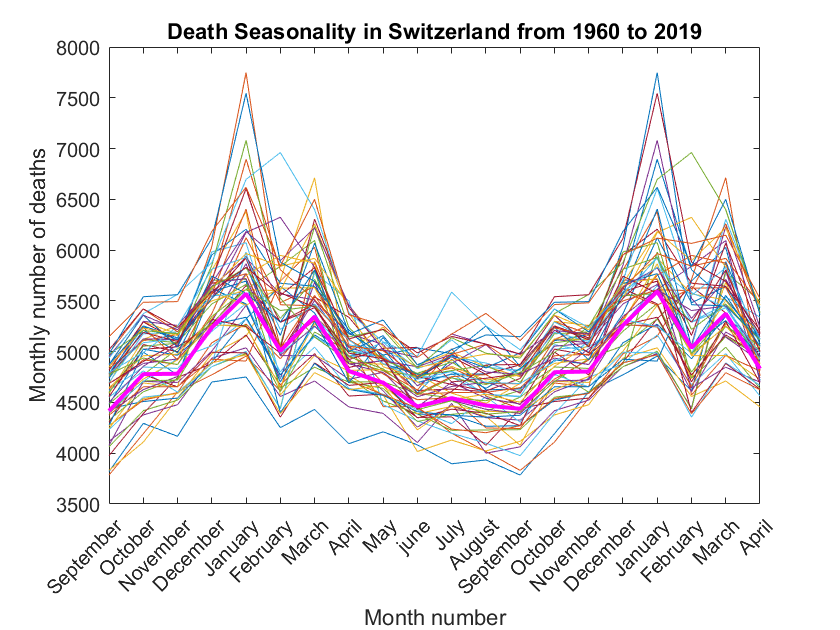

months ={'September', 'October', 'November', 'December', 'January', 'February', 'March', 'April', 'May', 'june', 'July', 'August', 'September', 'October', 'November', 'December', 'January', 'February', 'March', 'April'};

% Iteratively plot mortality vs month
merged_year = zeros(60, 20);

for year = 2:59
    
    last_year = myDeath(year - 1, :);
    current_year = myDeath(year, :);
    next_year = myDeath(year + 1, :);

    merged_year(year - 1, :) = [last_year(end-3:end), current_year, next_year(1:4)];

    plot(1:20, merged_year(year - 1, :))
    hold on

end

% Decorate the plot
plot(1:20, mean(merged_year), 'Color', "m", 'LineWidth', 2, 'LineStyle', "-")

title('Death Seasonality in Switzerland from 1960 to 2019')

xlabel('Month number')
ylabel('Monthly number of deaths')

xlim([1, 20])
xticks(1:20)

xticklabels(months)
xtickangle(45)
hold off

## Plot death seasonality in 3D

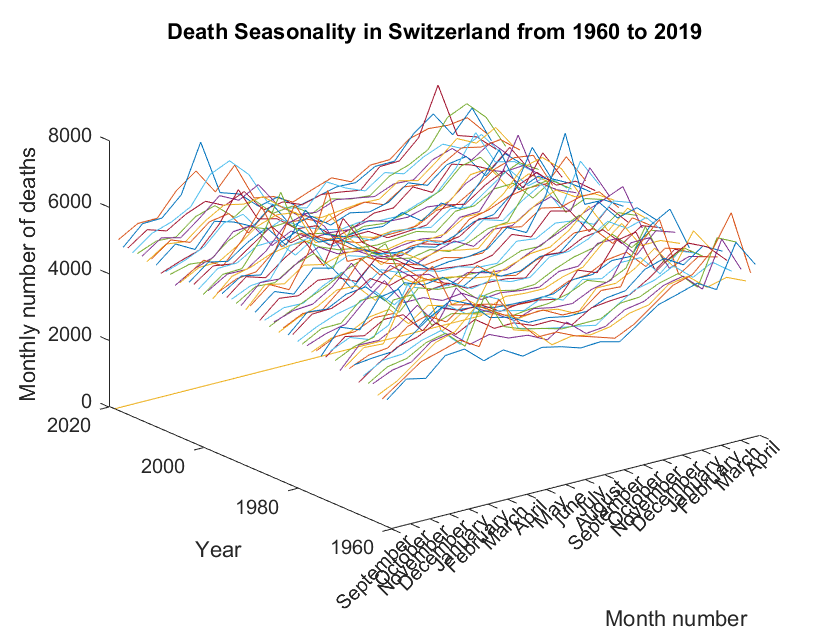

% Iteratively plot mortality vs month and year
for year = 2:60

    plot3(1:20, ones(1,20) * years(year), merged_year(year - 1, :))
    hold on

end

% Decorate the plot
xlabel('Month number')
ylabel('Year')
zlabel('Monthly number of deaths')

title('Death Seasonality in Switzerland from 1960 to 2019')

xlim([1, 20])
xticks(1:20)

xticklabels(months)
xtickangle(45)
hold off

## Normalise to population size

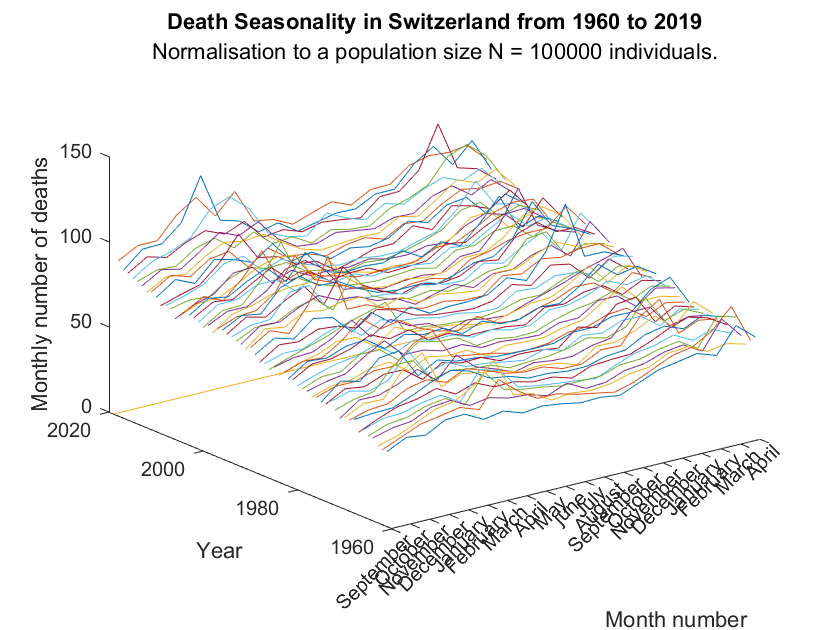

% Normalise to a population N = 100000
mySize = 100000;
norm_merged_year = merged_year ./ popSize(1:end) * mySize;

% Iteratively plot mortality vs month and year
for year = 2:60
    
    plot3(1:20, ones(1,20) * years(year), norm_merged_year(year - 1, :))
    hold on

end

% Decorate the plot
xlabel('Month number')
ylabel('Year')
zlabel('Monthly number of deaths')

title('Death Seasonality in Switzerland from 1960 to 2019')
subtitle(['Normalisation to a population size N = ', num2str(mySize), ' individuals.'])

xlim([1, 20])
xticks(1:20)

xticklabels(months)
xtickangle(45)
hold off